# Chapter 4, Section 6 (Part 2)

The goal of this activity is the introduction of **homogeneous coordinates**. Let's see why. Suppose we want to shift our image 2 units to the right. Then our mapping would be:


$$S\left(\pmatrix{x\cr y}\right)=\pmatrix{x+2\cr y}$$


Now, is this a linear transformation? Let's see if it satisfies $S(\vec u+\vec v)=S(\vec u)+S(\vec v)$. Using our definition above, 


$$S\left(\pmatrix{x_1\cr y_1}+\pmatrix{x_2\cr y_2}\right)=S\left(\pmatrix{x_1+x_2\cr y_1+y_2}\right)=\pmatrix{x_1+x_2+2\cr y_1+y_2}$$


but:


$$S\left(\pmatrix{x_1\cr x_2}\right)+S\left(\pmatrix{x_2\cr y_2}\right)=\pmatrix{x_1+2\cr y_1}+\pmatrix{x_2+2\cr y_2}=\pmatrix{x_1+x_2+4\cr y_1+y_2}$$


Note that these two are not the same, so $S$ fails the property $S(\vec u+\vec v)=S(\vec u)+S(\vec v)$ and $S$ is not a linear transformation. Thus, we cannot represent this mapping using a $2\times 2$ matrix as we did in the previous activity. 

To fix this problem, the homogeneous coordinates for the vector $\vec v=\pmatrix{x\cr y}\in \mathbb R^2$ are given by adding a 1, creating a $3\times 1$ vector.


$$\vec w=\pmatrix{x\cr y\cr 1}$$


Now, consider this matrix:


$$A=\pmatrix{1 & 0 & b_1\cr 0 & 1 & b_2\cr 0 & 0 & 1}$$


Let's see what this matrix does when it is applied to the homogeneous vector $\vec w$.


$$\begin{array}{rcl}
A\vec w&=&\pmatrix{1 & 0 & b_1\cr 0 & 1 & b_2\cr 0 & 0 & 1}\pmatrix{x\cr y\cr 1}\\
A\vec w&=&\pmatrix{x+b_1\cr y+b_2\cr 1}
\end{array}$$


If you focus on this matrix-vector multiplication, you will see that it will always return a 1 in the third position of the answer. If we just grab the first two components (in rows one and two) of the answer, we've described the following mapping


$$S\left(\pmatrix{x\cr y}\right)=\pmatrix{x+b_1\cr y+b_2}$$


which will shift $x$ horizontally by $b_1$ units and $y$ vertically by $b_2$ units. 

# Example #1

Let's draw a rectangle whose vertices are at (2,2), (3,2), (3,3), and (2,3). First, enter the x-values, which are 2, 3, 3, 2, and the y-values, which are 2, 2, 3, 3.

x=[2 3 3 2];
y=[2 2 3 3];

Now we can use the patch command to draw the rectangle and we'll set the axes to prettify our image.

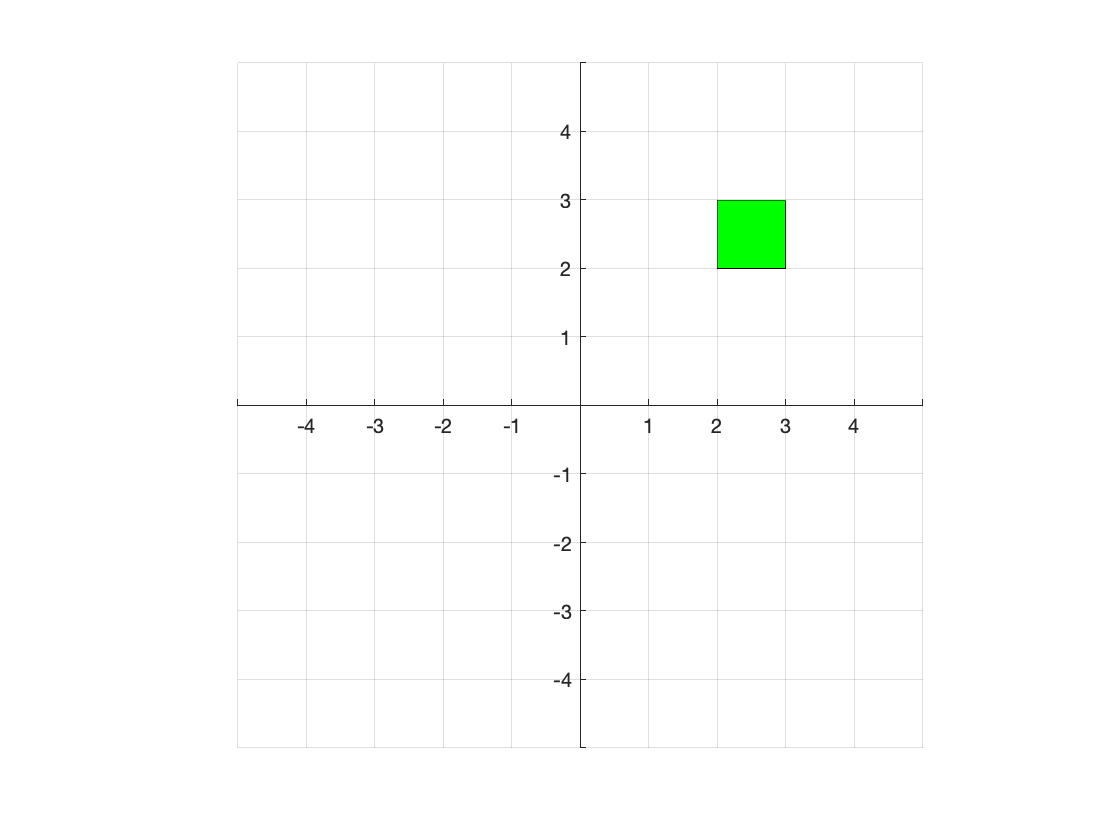

figure
x=[2 3 3 2];
y=[2 2 3 3];
patch(x,y,'g')
axis equal
axis([-5,5,-5,5])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';

Now, create a matrix that will shift the lower left corner of the rectangle to the origin; that is, shift the rectangle 2 units to the left and 2 units downward. 

**Solution: **Based on what we learned above, the matrix


$$A=\pmatrix{1 & 0 & -2\cr 0 & 1 & -2\cr 0 & 0 & 1}$$


should perform this task. Again, recall that one way to multiply matrix $A$ times matrix $B$ is $AB=\left\{A\vec b_1,\ A\vec b_2,\ \ldots,\ A\vec b_n\right\}$; that is, multiply matrix $A$ times each column of matrix $B$. Enter matrix $A$.

A=[1 0 -2;0 1 -2;0 0 1];

Now, let's enter the x-values and y-values of our points again.

x=[2 3 3 2];
y=[2 2 3 3];

So that these are in homogeneous coordinate style (necessary for multiplying by a $3\times 3$ matrix), we will need a third row of ones the same size as the first two rows.

pts=[x;y;ones(size(x))]

pts =      2     3     3     2
     2     2     3     3
     1     1     1     1


Each column is one of the points on our rectangle with a 1 added at the bottom to change them into homogeneous coordinates. Now, if we multiply this matrix pts by matrix $A$, it should produce our shifted points using the property $AB=\left\{A\vec b_1,\ A\vec b_2,\ \ldots,\ A\vec b_n\right\}$; that is, it will multiply matrix $A$ times each column of matrix pts.

Spts=A*pts

Spts =      0     1     1     0
     0     0     1     1
     1     1     1     1


Note that the four columns of this answer represent the points (0,0), (1,0), (1,1), and (0,1). Now, when we use the patch command, we'll snatch the first two rows with Spts(1,:) and Spts(2,:). Here is the full code.

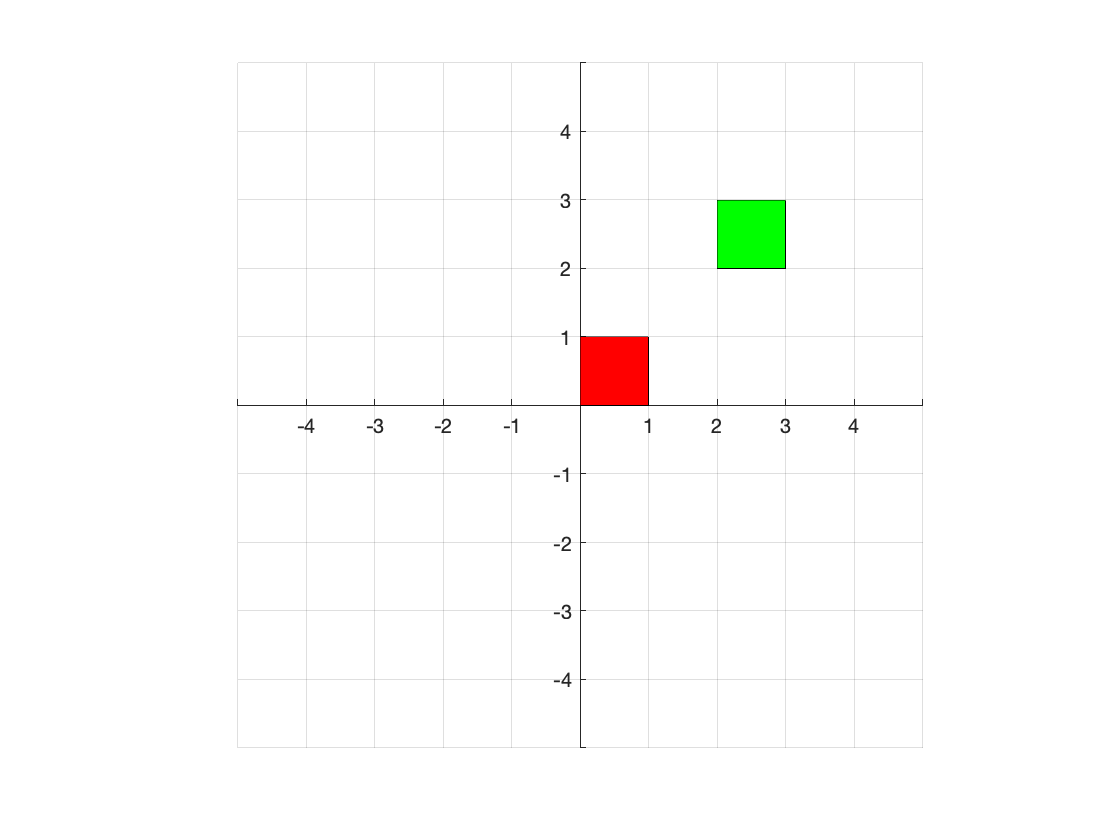

figure
x=[2 3 3 2];
y=[2 2 3 3];
patch(x,y,'g')
A=[1 0 -2;0 1 -2;0 0 1];
pts=[x;y;ones(size(x))];
Spts=A*pts;
patch(Spts(1,:),Spts(2,:),'r')
axis equal
axis([-5,5,-5,5])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';

Perfect. It shifted the lower left corner of our green rectangle to the origin; that is, two units to the left and two units downward.

# Example #2

Consider the following image.

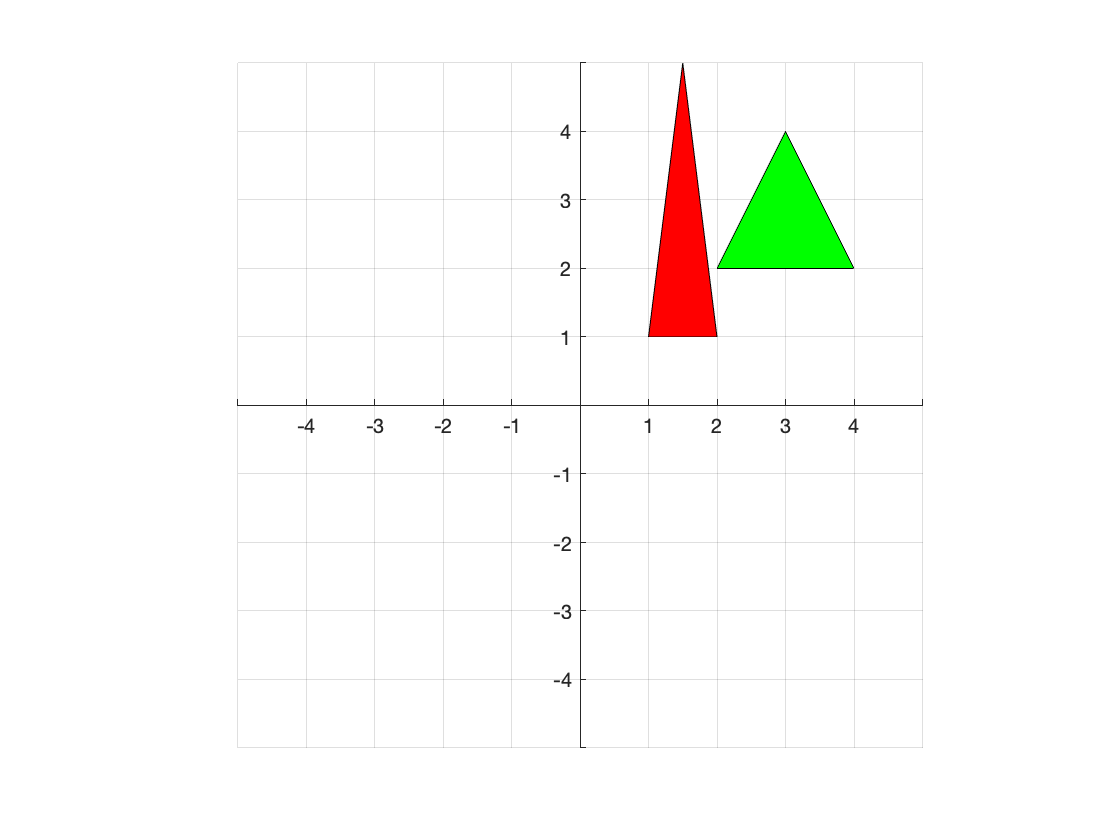

figure
x1=[2 4 3];
y1=[2 2 4];
patch(x1,y1,'g')
x2=[1 2 3/2];
y2=[1 1 5];
patch(x2,y2,'r')
axis equal
axis([-5,5,-5,5])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';

Find a single matrix that will transform the green triangle into the red triangle.

**Solution: **Note that the vertices of the green triangle are (2,2), (4,2), and (3,4). The matrix


$$A=\pmatrix{1 & 0 & -2\cr 0 & 1 & -2\cr 0 & 0 & 1}$$


will shift the triangle 2 units to the left and 2 units downward.

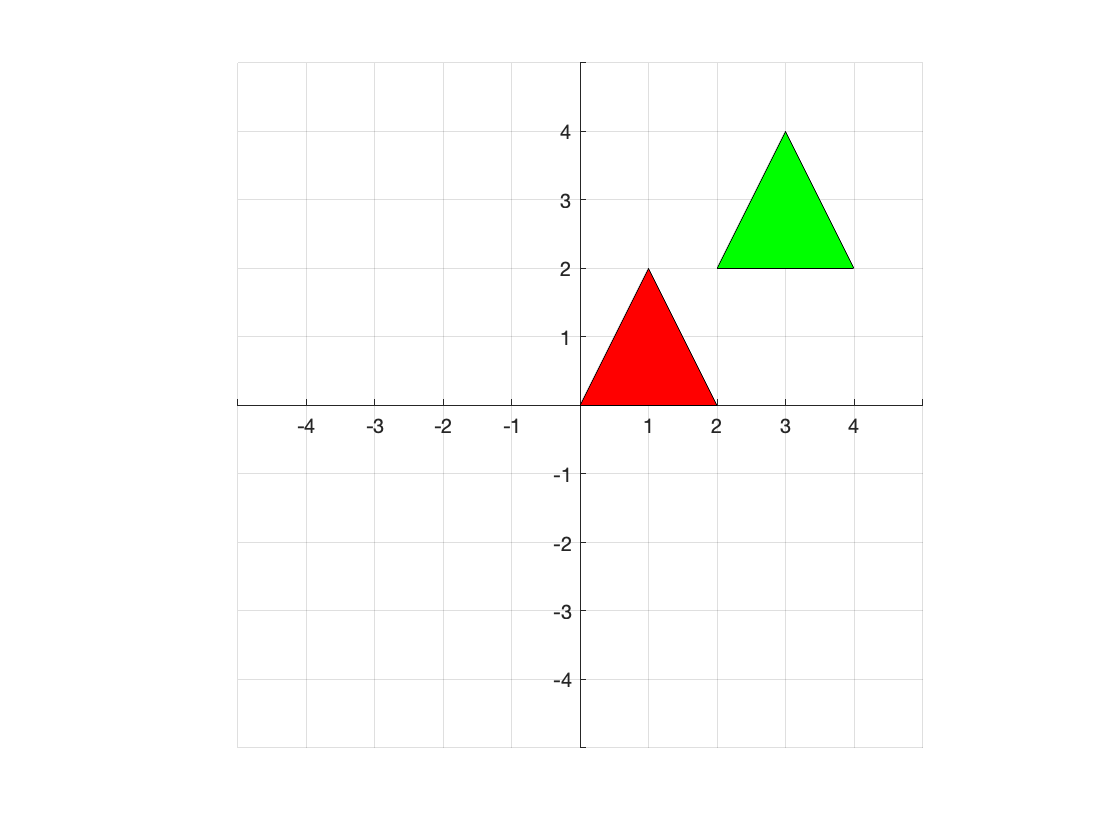

figure
x=[2 4 3];
y=[2 2 4];
patch(x,y,'g')
pts=[x;y;ones(size(x))];
A=[1 0 -2;0 1 -2;0 0 1];
Spts=A*pts;
patch(Spts(1,:),Spts(2,:),'r')
axis equal
axis([-5,5,-5,5])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';

Now, let's contract the x-values by 2 (divide by 2) and double the y-values by 2. The following matrix should perform the task.


$$B=\pmatrix{1/2 & 0 & 0\cr 0 & 2 & 0\cr 0 & 0 & 1}$$


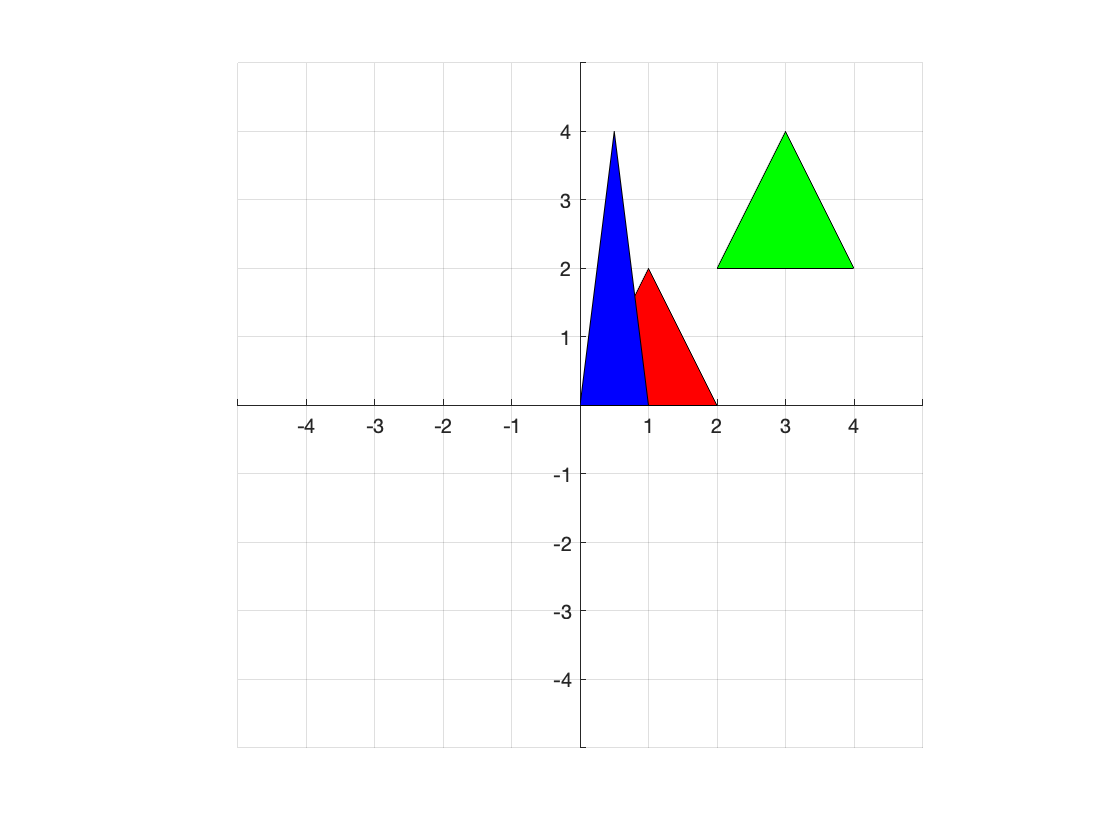

figure
x=[2 4 3];
y=[2 2 4];
patch(x,y,'g')
pts=[x;y;ones(size(x))];
A=[1 0 -2;0 1 -2;0 0 1];
Spts=A*pts;
patch(Spts(1,:),Spts(2,:),'r')
B=[1/2 0 0;0 2 0;0 0 1];
Tpts=B*Spts;
patch(Tpts(1,:),Tpts(2,:),'b')
axis equal
axis([-5,5,-5,5])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';

Now, let's shift the blue triangle to the right 1 and up 1. The following matrix should perform the task.


$$C=\pmatrix{1 & 0 & 1\cr 0 & 1 & 1\cr 0 & 0 & 1}$$


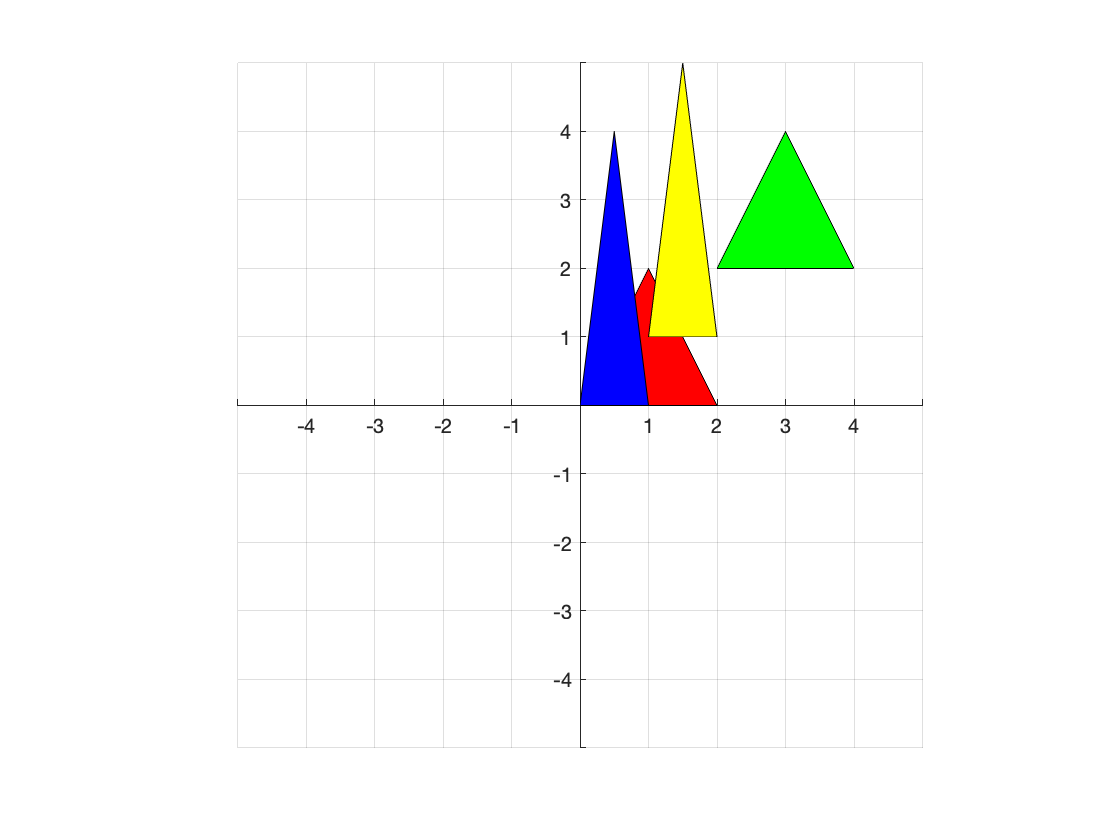

figure
x=[2 4 3];
y=[2 2 4];
patch(x,y,'g')
pts=[x;y;ones(size(x))];
A=[1 0 -2;0 1 -2;0 0 1];
Spts=A*pts;
patch(Spts(1,:),Spts(2,:),'r')
B=[1/2 0 0;0 2 0;0 0 1];
Tpts=B*Spts;
patch(Tpts(1,:),Tpts(2,:),'b')
C=[1 0 1;0 1 1;0 0 1];
Rpts=C*Tpts;
patch(Rpts(1,:),Rpts(2,:),'y')
axis equal
axis([-5,5,-5,5])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';

The yellow triangle appears to be our goal. Now, we started with the points of the green triangle, multiplied by matrix $A$, then $B$, then $C$. This means that we did the following


$$\vec y=CBA\vec x$$


where $\vec x$ was the original vertex, and $\vec y$ was the corresponding vertex in the resulting triangle, and we did this for the entire set of vertices. So, what is $CBA$ equal to? Let's ask Matlab for assistance (it would also be a fairly easy hand-calculation).

C*B*A

ans =     0.5000         0         0
         0    2.0000   -3.0000
         0         0    1.0000


So,


$$CBA=\pmatrix{1/2 & 0 & 0\cr 0 & 2 & -3\cr 0 & 0 & 1}$$


Let's try this matrix to see if it directly transposes the green triangle to the red triangle.

figure
x=[2 4 3];
y=[2 2 4];
patch(x,y,'g')
pts=[x;y;ones(size(x))];
CBA=C*B*A;
Spts=CBA*pts;
patch(Spts(1,:),Spts(2,:),'r')
axis equal
axis([-5,5,-5,5])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';

Perfect, we're done.

# Example #3

Find a transformation that will rotate a point $(x,y)$ about the origin.

**Solution: ** Let's start with an image. Picture below is a unit circle (radius 1). We've rotated the point at $(x,y)$ to the point $(u,v)$ by an angle $\theta$. In trigonometry, we learned that if the angle is $\alpha$, then the coordinates of the point on the unit circle are $(x,y)=(\cos\alpha,\sin\alpha)$. Our second point is rotated by an angle of $\theta+\alpha$, so its coordinates are $(u,v)=(\cos(\theta+\alpha),\sin(\theta+\alpha))$.

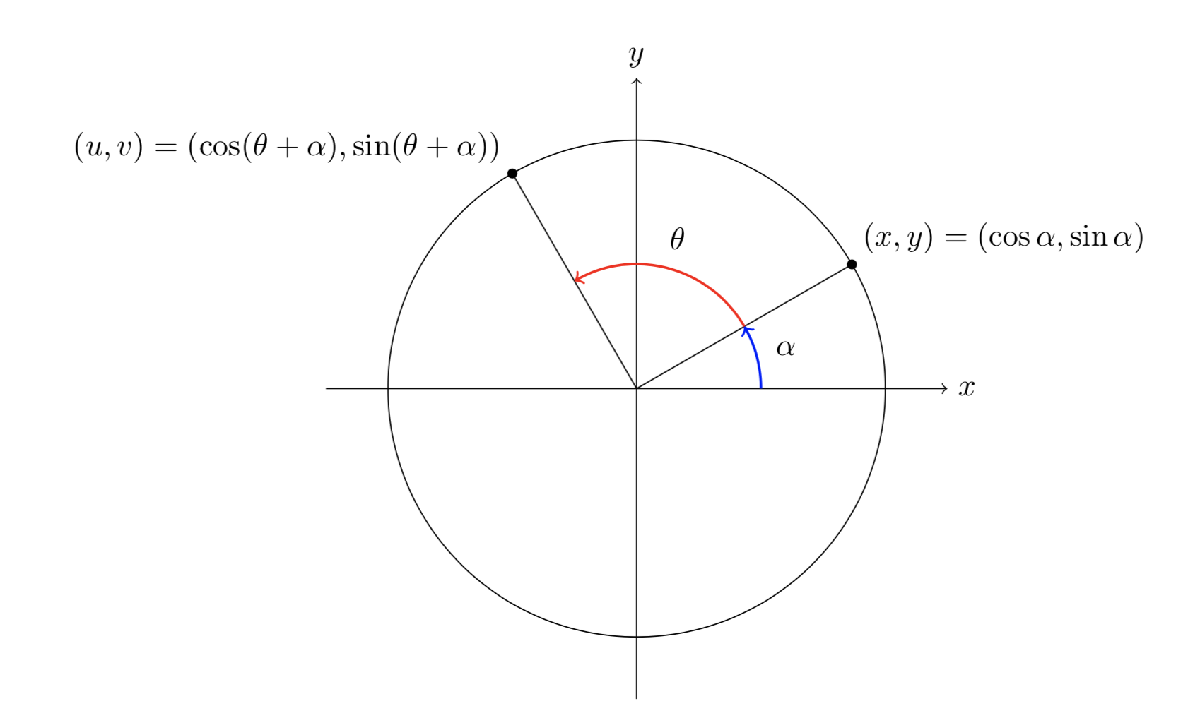

Now we can use the cosine expansion identity to expand $u$.


$$\begin{array}{rcl}
u&=&\cos(\theta+\alpha)\\
u&=&\cos\theta\cos\alpha-\sin\theta\sin\alpha
\end{array}$$


But $x=\cos\alpha$ and $y=\sin\alpha$, so if we make these replacements, we get:


$$u=(\cos\theta)x-(\sin\theta)y$$


Now we can use the sine expansion identity to expand $v$.


$$\begin{array}{rcl}
v&=&\sin(\theta+\alpha)\\
v&=&\sin\theta\cos\alpha+\sin\alpha\cos\theta
\end{array}$$


But $x=\cos\alpha$ and $y=\sin\alpha$, so if we make these replacements, we get:


$$v=(\sin\theta)x+(\cos\theta)y$$


Now, we have a system of two equations.


$$\begin{array}{rcl}
u&=&(\cos\theta)x-(\sin\theta)y\\
v&=&(\sin\theta)x+(\cos\theta)y
\end{array}$$


We can write this system in matrix form.


$$\pmatrix{u\cr v}=\pmatrix{\cos\theta & -\sin\theta\cr \sin\theta & \cos\theta}\pmatrix{x\cr y}$$


Therefore, the rotation matrix


$$\pmatrix{\cos\theta & -\sin\theta\cr \sin\theta & \cos\theta}$$


will rotate the point $(x,y)$ by $\theta$ radians (or degrees) counterclockwise about the origin. Now, let's see if this works. Consider the following image.

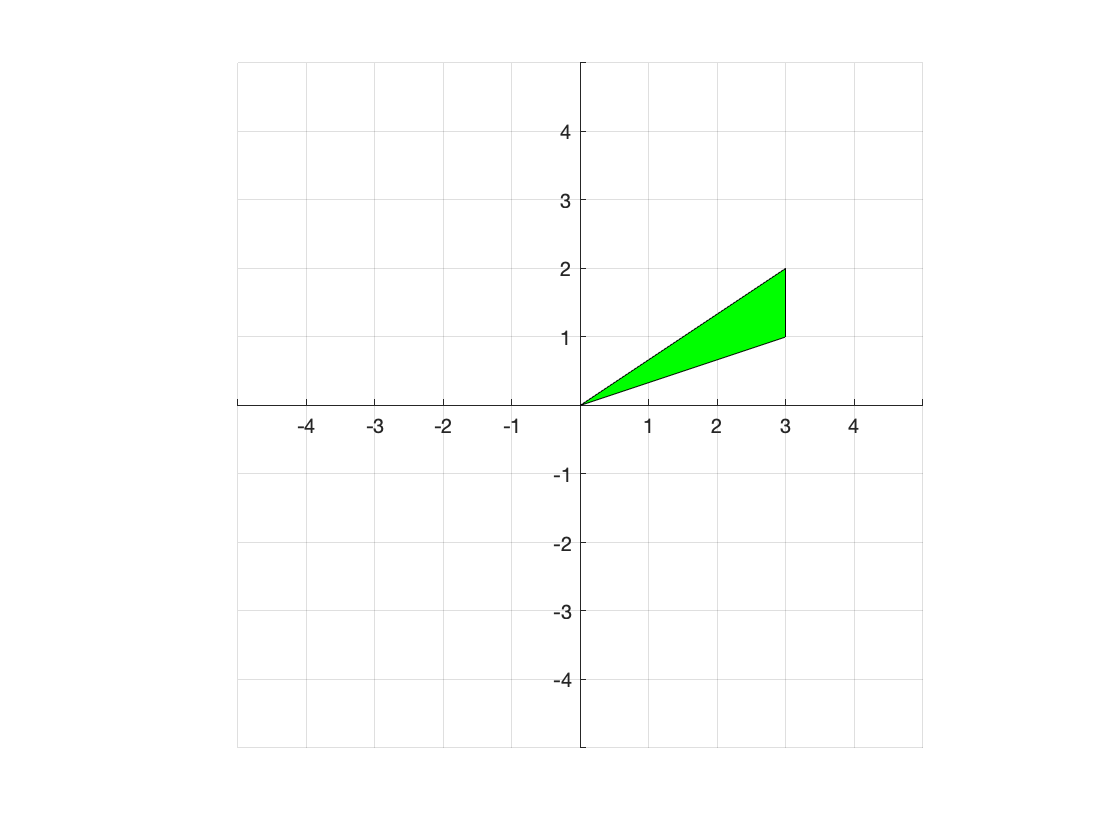

figure
x=[0 3 3];
y=[0 1 2];
patch(x,y,'g')
axis equal
axis([-5,5,-5,5])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';

Now, let's rotate this image $\pi/2$ radians counterclockwise.

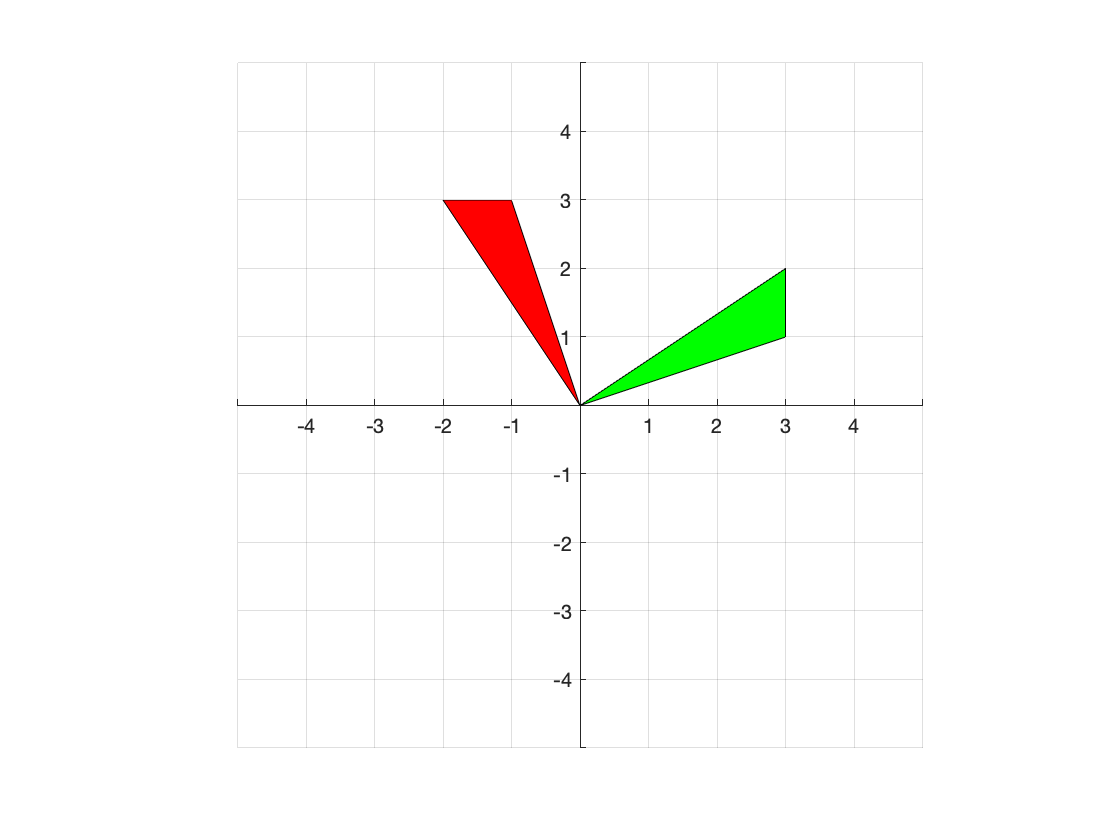

figure
x=[0 3 3];
y=[0 1 2];
patch(x,y,'g')
pts=[x;y];
A=[cos(pi/2) -sin(pi/2);sin(pi/2) cos(pi/2)];
Spts=A*pts;
patch(Spts(1,:),Spts(2,:),'r')
axis equal
axis([-5,5,-5,5])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';

Perfect! That worked. :-)